# Noisy case code

## Import data (from camera 1)

%%% Imports data
Dataset_Noisy = 'Noisy_Case';
Camera_Noisy = 'cam1_2.mat';

camData_Noisy = importCamData(Dataset_Noisy,Camera_Noisy);

## Camera 1

### Shows uncropped and cropped frame in colour

%%% Shows uncropped and cropped frame in colour
frame_Noisy = 1

frame_Noisy = 1

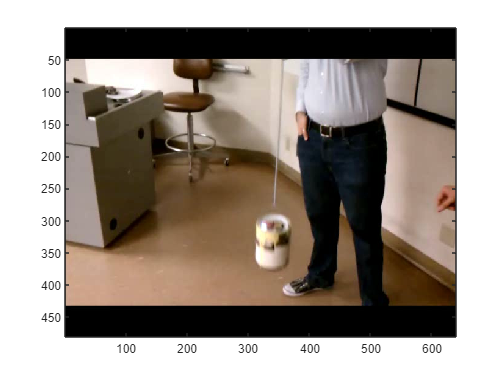


camImage_Noisy = image(camData_Noisy.vidFrames1_2(:,:,:,frame_Noisy));

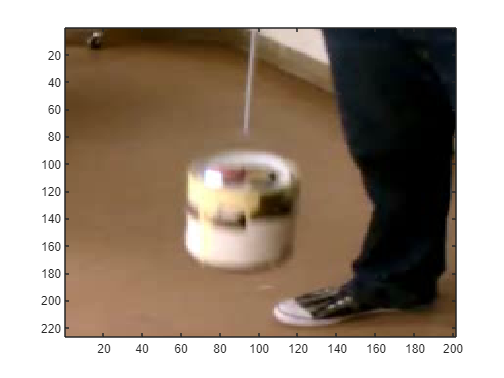

width_Noisy = 250:450;
height_Noisy = 200:425;
croppedFrame_Noisy = camData_Noisy.vidFrames1_2(height_Noisy,width_Noisy,:,frame_Noisy);
croppedFrame1_Noisy = camData_Noisy.vidFrames1_2(height_Noisy,width_Noisy,:,1);
camImageCropped_Noisy = image(croppedFrame_Noisy);

### Shows frame of grayscale image

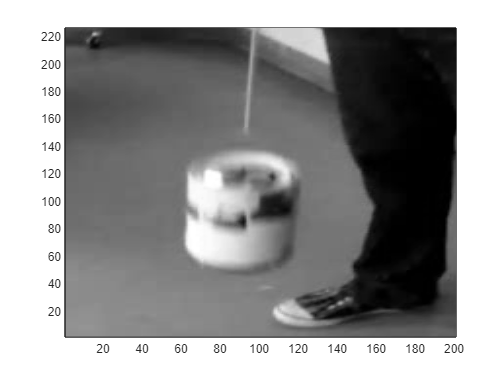

%%% Shows a frame from any camera as a grayscale colourmap (to locate
%%% locations of particular points

%%% Modified from: Data-Driven Modeling & Scientific Computation: 
%%% Methods for Complex Systems & Big Data 
%%% by J. NATHAN KUTZ


a_Noisy = flipud( double( rgb2gray( camData_Noisy.vidFrames1_2(height_Noisy,width_Noisy,:,1) )));
% a_Noisy = flipud( double( rgb2gray( camData_Noisy_2.vidFrames2_2(height_Noisy_2,width_Noisy_2,:,1) )));
% a_Noisy = flipud( double( rgb2gray( camData_Noisy_3.vidFrames3_2(height_Noisy_3,width_Noisy_3,:,1) )));

% x = 1:640;
% y = 1:480;
% [X,Y]=meshgrid(x,y);
% pcolor(X,Y,a)
pcolor(a_Noisy)
shading interp
colormap("gray")

% set(gca,'Xtick',[],'Ytick',[],'Ztick',[])


### Finds and shows cap pixels (using both methods)

%%% Finds and shows cap pixels
x_Noisy = 77;
y_Noisy = 116;


r_Noisy = croppedFrame1_Noisy(end-y_Noisy,x_Noisy,1)

r_Noisy = uint8
255

g_Noisy = croppedFrame1_Noisy(end-y_Noisy,x_Noisy,2)

g_Noisy = uint8
255

b_Noisy = croppedFrame1_Noisy(end-y_Noisy,x_Noisy,3)

b_Noisy = uint8
254

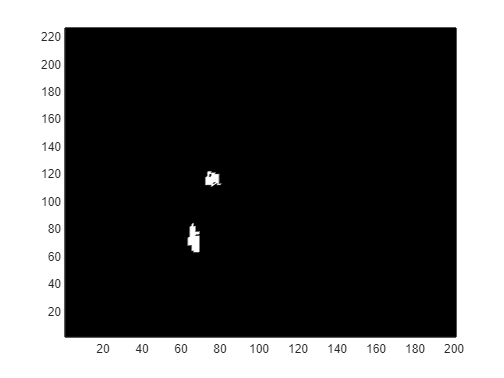


d_Noisy = 5;
cap_Pixels_Noisy = ((croppedFrame_Noisy(:,:,1) >= r_Noisy - d_Noisy) & (croppedFrame_Noisy(:,:,1) <= r_Noisy + d_Noisy)) ...
            &((croppedFrame_Noisy(:,:,2) >= g_Noisy - d_Noisy) & (croppedFrame_Noisy(:,:,2) <= g_Noisy + d_Noisy)) ...
            &((croppedFrame_Noisy(:,:,3) >= b_Noisy - d_Noisy) & (croppedFrame_Noisy(:,:,3) <= b_Noisy + d_Noisy));

pcolor(flipud(cap_Pixels_Noisy))
shading interp
colormap("gray")

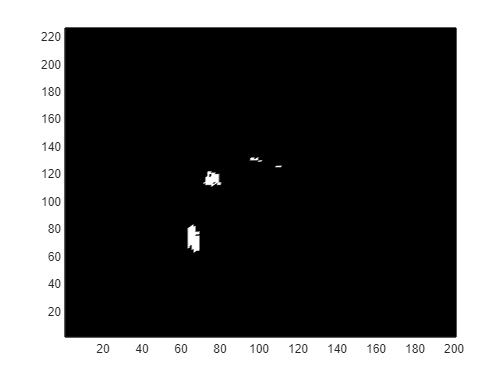


cap_Pixels_Noisy_2 = getCapPixelsBright(croppedFrame_Noisy,d_Noisy);

pcolor(flipud(cap_Pixels_Noisy_2))
shading interp
colormap("gray")

### Finds x and y coordinate of average of cap pixels

%%% Finds x and y coordinate of average of cap pixels
bounds_Noisy = Boundaries(cap_Pixels_Noisy)

bounds_Noisy = 120

[top_Noisy,bottom_Noisy,left_Noisy,right_Noisy] = Boundaries(cap_Pixels_Noisy)

top_Noisy = 120

bottom_Noisy = 62

left_Noisy = 64

right_Noisy = 80


[x_Noisy,y_Noisy] = centre(top_Noisy,bottom_Noisy,left_Noisy,right_Noisy)

x_Noisy = 72

y_Noisy = 91

[x_avg_Noisy,y_avg_Noisy] = centre_avg(cap_Pixels_Noisy)

x_avg_Noisy = 70.4621

y_avg_Noisy = 88.4345

### Finds position of cap and stores it into a vector

%%% Finds position of cap and stores it into a vector
numFrames_Noisy = size(camData_Noisy.vidFrames1_2(1,1,1,:),4);
width_Noisy = 250:450;
height_Noisy = 200:425;
croppedFrame1_Noisy = camData_Noisy.vidFrames1_2(height_Noisy,width_Noisy,:,1);

x_Noisy = 77;
y_Noisy = 116;
d_Noisy = 20;

X_0_Noisy = zeros(1,numFrames_Noisy);
Y_0_Noisy = zeros(1,numFrames_Noisy);

for i = 1:numFrames_Noisy
    croppedFrame_Noisy = camData_Noisy.vidFrames1_2(height_Noisy,width_Noisy,:,i);
    cap_Pixels_Noisy = getCapPixels(croppedFrame1_Noisy,croppedFrame_Noisy,x_Noisy,y_Noisy,d_Noisy);
    
    [x_avg_Noisy,y_avg_Noisy] = centre_avg(cap_Pixels_Noisy);
    X_0_Noisy(i) = x_avg_Noisy;
    Y_0_Noisy(i) = y_avg_Noisy;
end

X_0_Noisy

X_0_Noisy =    72.6322   72.6169   72.6053   72.5925   72.6053   72.5925   77.1497   77.0548   82.2101   82.3182   84.4891   86.0662   85.7767   86.4674   86.3993   85.5352   85.6719   91.7836   90.7000   90.3543   93.4958   93.5042   97.5150   97.5216  105.1841  112.3827  112.4128  101.2717  101.4239   91.8462   91.8789  100.3416  102.1560  102.1134   91.6308   91.4828   92.9779   92.8922   96.4022   87.6103   87.5567   81.9071   82.0534   89.9798   90.1940   96.2432   93.2226   93.2246   86.0793   86.0708


Y_0_Noisy

Y_0_Noisy =    90.2644   90.0766   89.5865   89.6830   89.5865   89.6830   83.1122   83.0342   76.7751   77.3848   73.3551   74.1451   73.7736   77.8213   77.7645   82.3125   82.4805   90.9366   92.9273   92.1794  108.0127  107.9790  119.6996  119.8147  123.6617  131.3394  131.2064  151.5489  151.7283  148.2692  148.3320  149.7160  151.1680  151.1255  149.9615  149.7931  143.8382  143.8625  134.9638  137.1744  137.0258  119.4107  119.4626  108.1650  108.4114   94.3581   82.7810   82.9167   73.4890   73.5973


### Plots X and Y for camera 1

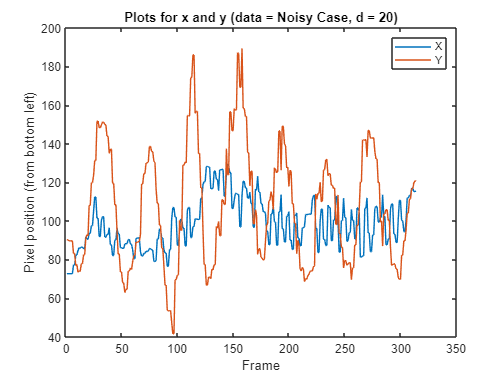

%%% Plots X and Y
plot(X_0_Noisy)
title('Plots for x and y (data = Noisy Case, d = 20)')
xlabel('Frame')
ylabel('Pixel position (from bottom left)')
hold on
plot(Y_0_Noisy)
legend('X','Y')
hold off

### Finds and plots X and Y for camera 1 for any d (with function that uses initial position)

%%% Finds and plots X and Y for any d (with function)
width_Noisy = 250:450;
height_Noisy = 200:425;
x_Noisy = 77;
y_Noisy = 116;
d1_Noisy = 50;

[X_11_Noisy,Y_11_Noisy] = getXY(camData_Noisy.vidFrames1_2,width_Noisy,height_Noisy,x_Noisy,y_Noisy,d1_Noisy)

X_11_Noisy =    82.4950   82.4950   83.1043   83.0442   83.1020   83.0442   84.3576   84.5152   87.1412   87.1274   89.7220   90.7204   90.6711   91.5380   91.7945   92.8046   92.6513   95.6906  100.7366  100.7266  100.6312  100.5932  104.9870  104.8405  115.9440  117.1174  117.0517  100.5943  100.7250   97.5920   97.4547  104.2027  107.4637  107.4333   97.3330   97.1713  100.3511  100.2317  106.1680   91.8170   91.7032   91.9936   91.3398   95.3991   95.3695  105.9272  105.7224  105.7167   99.1330   99.2075


Y_11_Noisy =    92.9228   92.9178   94.1959   94.0314   93.8775   94.0314   84.8108   85.2326   80.9773   80.5374   80.7363   80.3487   79.7868   82.6385   83.3400   84.4678   84.2492   88.9393   97.9917   97.7432  105.6770  105.8446  114.3420  114.0636  126.7201  129.2383  129.0112  133.8927  134.3046  144.6765  144.8695  143.2095  149.0860  148.9033  145.6250  145.1703  146.6008  146.2495  137.8994  127.5739  127.1992  126.2987  124.3777  108.6067  108.6074  108.5889   96.1535   95.8971   92.1695   92.5850


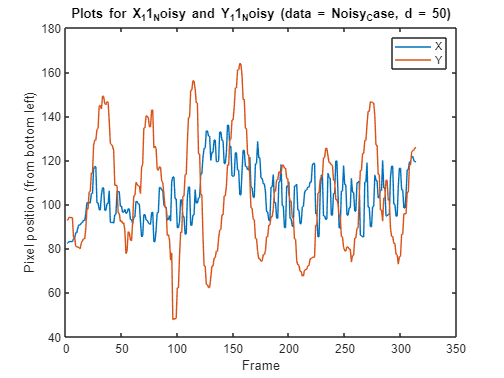


plotXY(X_11_Noisy,Y_11_Noisy,d1_Noisy,Dataset_Noisy)

### Finds and plots X and Y for camera 1 for any d (with function that uses brightness)

%%% Finds and plots X and Y for any d (with function)
width_Noisy = 250:450;
height_Noisy = 200:425;
d2_Noisy = 50;

[X_12_Noisy,Y_12_Noisy] = getXYBright(camData_Noisy.vidFrames1_2,width_Noisy,height_Noisy,d2_Noisy)

X_12_Noisy =    85.1417   85.0393   84.6203   84.6288   84.7485   84.6866   84.9023   84.7159   84.3127   84.4696   84.8805   84.5767   84.9758   85.3007   85.2511   83.2250   83.1422   80.7395   83.0430   83.0798   86.6043   86.4669   84.6601   84.8005   86.0031   85.5839   85.4911   79.9838   79.8482   84.9831   85.3697   82.6107   81.5869   81.5205   82.0640   81.8787   83.2355   83.2264   84.5282   81.4616   81.5119   84.6035   84.5511   83.1609   82.9932   82.9264   85.7032   85.3526   82.8354   82.7389


Y_12_Noisy =    63.3603   63.4449   63.0572   63.2572   63.1831   63.2492   59.8319   59.7577   56.7477   56.8985   56.0937   54.6799   54.7535   54.5755   54.5779   55.0928   55.0238   54.9224   55.3939   55.3968   58.5494   58.3280   57.6568   57.6258   59.2631   59.1425   59.0332   63.1540   63.0186   64.0226   64.3295   66.2908   64.2944   63.9699   64.2088   64.2348   66.7513   66.7989   64.3853   65.3685   65.3884   63.5233   63.5078   62.5215   62.3501   59.6316   59.5022   59.4702   59.4941   59.4561


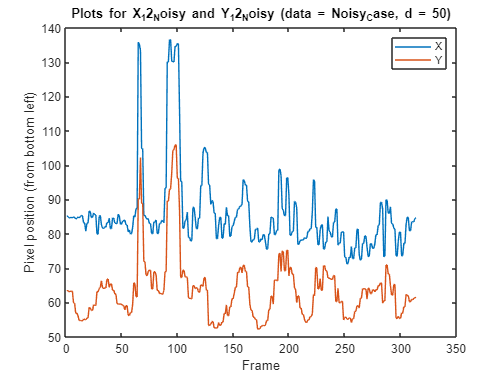


plotXY(X_12_Noisy,Y_12_Noisy,d2_Noisy,Dataset_Noisy)

## Camera 2

### Imports data

%%% Imports data from second camera
Camera_Noisy_2 = 'cam2_2.mat';

camData_Noisy_2 = importCamData(Dataset_Noisy,Camera_Noisy_2);


### Shows uncropped and cropped frame in colour

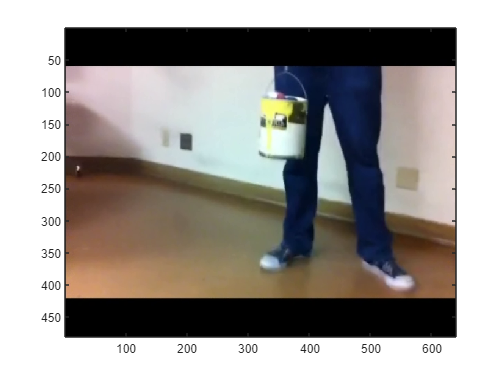

%%% Shows uncropped and cropped frame in colour for 2nd camera
frame_Noisy_2 = 300;

camImage_Noisy_2 = image(camData_Noisy_2.vidFrames2_2(:,:,:,frame_Noisy_2));

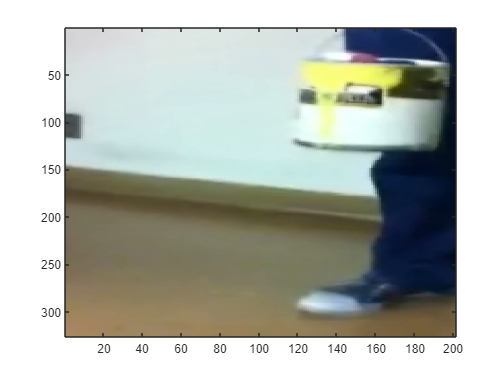

width_Noisy_2 = 200:400;
height_Noisy_2 = 75:400;
croppedFrame_Noisy_2 = camData_Noisy_2.vidFrames2_2(height_Noisy_2,width_Noisy_2,:,frame_Noisy_2);
camImageCropped_Noisy_2 = image(croppedFrame_Noisy_2);

### Finds and plots X and Y for camera 2 (using initial position)

%%% Finds and plots X and Y for camera 2
width_Noisy_2 = 200:400;
height_Noisy_2 = 100:400;
x_Noisy_2 = 115;
y_Noisy_2 = 45;
d1_Noisy_2 = 50;

[X_21_Noisy,Y_21_Noisy] = getXY(camData_Noisy_2.vidFrames2_2,width_Noisy_2,height_Noisy_2,x_Noisy_2,y_Noisy_2,d1_Noisy_2)

X_21_Noisy =    57.8836   57.8982   44.2586   40.9614   43.7833   40.6361   40.6876   43.6171   48.4775   47.6067   52.3946   52.6461   61.0060   73.0333   96.1172   98.7984   98.8058   92.6456   84.5316   72.6050   59.8655   59.7352   52.5249   46.2413   37.0583   37.4397   37.4965   31.4605   33.3998   31.8292   35.6717   35.7272   34.4796   25.6369   28.9748   29.0670   34.5611   37.9796   41.2649   40.7516   36.8271   36.7122   35.5882   36.6054   41.1665   44.1025   43.7102   46.0685   48.6771   52.3267


Y_21_Noisy =   151.6071  151.6577  144.6384  142.3024  142.9733  141.9187  141.9843  148.3269  156.8025  164.1329  176.3287  176.1776  192.7816  212.9987  221.7135  228.5069  228.3223  226.4507  217.2455  214.0097  194.2045  194.1098  187.1444  176.8044  165.0745  167.6262  167.1714  152.7002  150.7369  152.0465  140.4007  140.2442  148.4334  140.9928  140.1993  140.3913  151.4242  155.3323  160.3530  159.2994  156.2829  156.3140  149.5552  149.0005  149.5676  157.1570  156.7296  163.4554  171.1923  176.5259


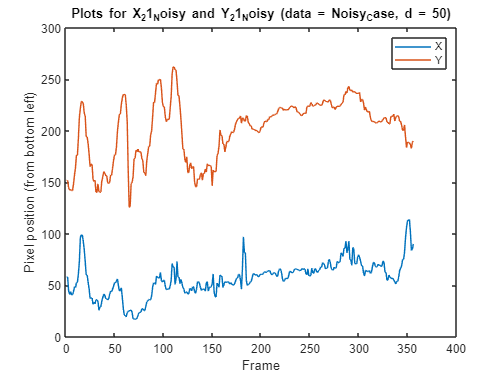


plotXY(X_21_Noisy,Y_21_Noisy,d1_Noisy_2,Dataset_Noisy)

### Finds and plots X and Y for camera 2 (using brightness)

%%% Finds and plots X and Y for camera 2
width_Noisy_2 = 200:400;
height_Noisy_2 = 100:400;
d2_Noisy_2 = 7.5;

[X_22_Noisy,Y_22_Noisy] = getXYBright(camData_Noisy_2.vidFrames2_2,width_Noisy_2,height_Noisy_2,d2_Noisy_2)

X_22_Noisy =   119.2658  119.3228  100.2091  101.2000  116.9622   88.3636   89.5718  101.3662  104.3981  112.3929  111.2963  112.5000  126.1880  138.0638  107.6835   62.3343   78.5608   89.8656  116.4698   56.4160   81.1974   77.3333   54.1930   53.8630   46.9643   81.7925   82.3023   61.1794   53.2525   52.1233   62.3509   62.0880   58.1938   47.3634   61.3676   61.5893   62.7061   64.3062   70.9246   69.4555   57.9885   57.9912   63.9826   70.0210   77.9201   89.5505   89.5134   94.9948  105.0402  117.9648


Y_22_Noisy =    36.3671   36.3481   32.8455   29.7273   30.6865   18.6449   19.2338   38.9155   62.5370  144.1786  169.8148  167.8529  206.1026  227.5532  239.9784  257.7209  257.3812  246.9382  258.5690  276.5382  251.1184  253.6377  204.4386  234.8493  112.2857  155.2642  155.1163   74.9410   51.5118   63.3566   22.3019   22.0480   30.1318   22.6942   22.3270   23.1480   24.0753   26.0705   19.4379   17.7363   20.1193   20.2026   16.7886   28.2180   37.1065   67.2753   67.4866   86.4817  108.2563  141.3592


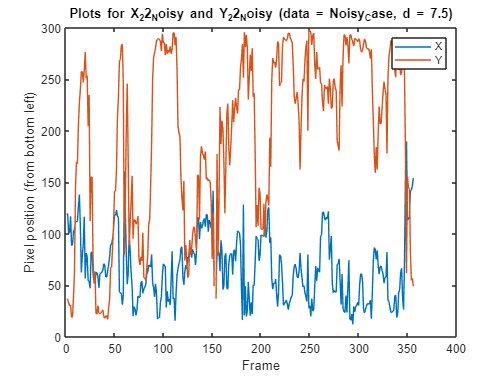


plotXY(X_22_Noisy,Y_22_Noisy,d2_Noisy_2,Dataset_Noisy)

## Camera 3

### Import data

%%% Imports data from third camera
Camera_Noisy_3 = 'cam3_2.mat';

camData_Noisy_3 = importCamData(Dataset_Noisy,Camera_Noisy_3);


### Shows uncropped and cropped frame in colour

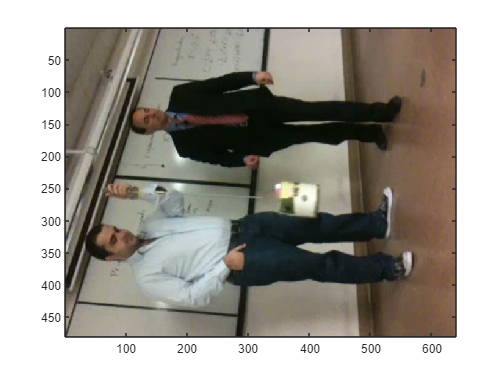

%%% Shows uncropped and cropped frame in colour for 2nd camera
frame_Noisy_3 = 1;

camImage_Noisy_3 = image(camData_Noisy_3.vidFrames3_2(:,:,:,frame_Noisy_3));

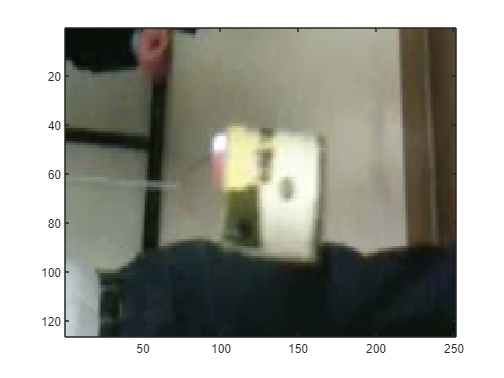

width_Noisy_3 = 250:500;
height_Noisy_3 = 200:325;
croppedFrame_Noisy_3 = camData_Noisy_3.vidFrames3_2(height_Noisy_3,width_Noisy_3,:,frame_Noisy_3);
camImageCropped_Noisy_3 = image(croppedFrame_Noisy_3);

### Finds and plots X and Y for camera 3 (using initial position)

%%% Finds and plots X and Y for camera 3
width_Noisy_3 = 250:500;
height_Noisy_3 = 200:325;
x_Noisy_3 = 100;
y_Noisy_3 = 80;
d1_Noisy_3 = 50;

[X_31_Noisy,Y_31_Noisy] = getXY(camData_Noisy_3.vidFrames3_2,width_Noisy_3,height_Noisy_3,x_Noisy_3,y_Noisy_3,d1_Noisy_3)

X_31_Noisy =   142.2697  142.2775  148.8143  148.8113  157.3887  157.2999  171.5465  171.4723  184.2068  183.7411  196.2503  196.1636  203.6336  203.6706  207.5567  207.5096  206.8701  206.8714  201.2787  201.3712  197.4778  197.4043  194.5078  194.5570  184.3379  184.1180  157.2797  157.0543  157.1389  143.2514  142.9941  137.3825  137.2301  125.5603  125.1937  110.6313  110.8696  112.3032  112.1301  118.9399  118.8791  123.4007  123.2665  127.3985  127.5290  137.9827  138.8769  160.4835  160.7745  174.7953


Y_31_Noisy =    62.0270   62.0208   61.8075   61.8006   60.5549   60.5507   60.4811   60.5102   60.3059   60.4497   59.8867   60.0971   58.3514   58.1290   58.5150   58.2331   59.7618   59.5486   58.0440   57.9557   53.1550   53.2012   49.1961   49.2220   52.0218   52.0854   56.8685   56.9304   56.9194   51.5852   51.7680   50.8772   50.9609   54.6571   54.5632   58.2112   58.1363   57.4983   57.6240   58.0240   58.0637   60.3146   60.3844   60.8087   60.7829   61.7747   61.2516   61.1249   61.0095   63.9531


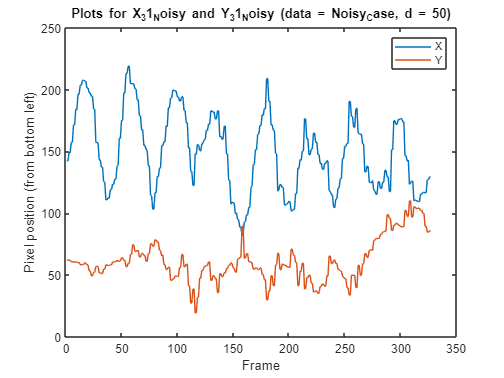


plotXY(X_31_Noisy,Y_31_Noisy,d1_Noisy_3,Dataset_Noisy)

### Finds and plots X and Y for camera 3 (using brightness)

%%% Finds and plots X and Y for camera 3
width_Noisy_3 = 250:500;
height_Noisy_3 = 200:350;
d2_Noisy_3 = 20;

[X_32_Noisy,Y_32_Noisy] = getXYBright(camData_Noisy_3.vidFrames3_2,width_Noisy_3,height_Noisy_3,d2_Noisy_3)

X_32_Noisy =   127.3754  128.0492  128.8816  127.6178  122.3406  121.8771  114.8645  115.5561  115.0411  114.4463  105.5915  104.2279  106.8326  107.1498  104.4279  105.4769  108.3341  112.4054  109.5902  109.3586  104.2924  104.8164   96.9425   92.3141   90.4703   87.7859  105.3680  108.9913  108.9757  119.3063  114.4726  114.3460  114.0094  113.8595  115.9483  122.1857  124.5842  122.4176  120.5453  118.1846  116.0789  109.1644  110.3907  113.0646  112.4367   92.8525   93.7238   79.8110   78.5182   72.3818


Y_32_Noisy =    59.0057   58.2333   65.6408   64.6477   64.2222   64.4734   63.2837   62.8179   66.4730   66.4504   66.7168   66.6569   62.9944   63.2651   61.6582   61.6954   64.2583   65.1106   66.5226   67.4538   66.1107   66.1405   62.9087   63.0829   63.9406   63.9880   65.0480   65.5564   65.3622   61.8582   62.1230   60.8046   61.3217   63.4905   62.9636   63.7758   63.4067   67.3411   67.9019   69.5287   68.1276   73.2192   73.1376   73.4032   73.0339   73.6183   73.0403   70.8743   70.8707   71.3250


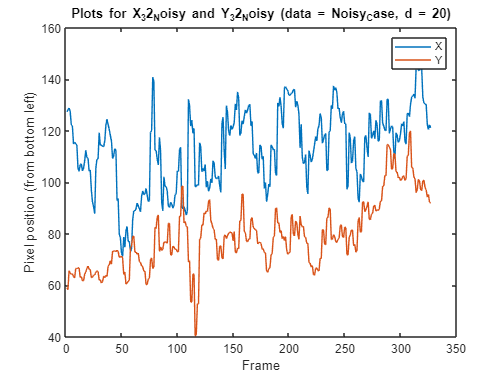


plotXY(X_32_Noisy,Y_32_Noisy,d2_Noisy_3,Dataset_Noisy)

## PCA

### Merge cameras' X and Y data

sz_Noisy = min( [size(X_11_Noisy,2), size(X_21_Noisy,2), size(X_31_Noisy,2)] )

sz_Noisy = 314


X_Noisy = cat( 1,X_11_Noisy(1:sz_Noisy),Y_11_Noisy(1:sz_Noisy),X_21_Noisy(1:sz_Noisy),Y_21_Noisy(1:sz_Noisy),X_31_Noisy(1:sz_Noisy),Y_31_Noisy(1:sz_Noisy) )

X_Noisy =    82.4950   82.4950   83.1043   83.0442   83.1020   83.0442   84.3576   84.5152   87.1412   87.1274   89.7220   90.7204   90.6711   91.5380   91.7945   92.8046   92.6513   95.6906  100.7366  100.7266  100.6312  100.5932  104.9870  104.8405  115.9440  117.1174  117.0517  100.5943  100.7250   97.5920   97.4547  104.2027  107.4637  107.4333   97.3330   97.1713  100.3511  100.2317  106.1680   91.8170   91.7032   91.9936   91.3398   95.3991   95.3695  105.9272  105.7224  105.7167   99.1330   99.2075
   92.9228   92.9178   94.1959   94.0314   93.8775   94.0314   84.8108   85.2326   80.9773   80.5374   80.7363   80.3487   79.7868   82.6385   83.3400   84.4678   84.2492   88.9393   97.9917   97.7432  105.6770  105.8446  114.3420  114.0636  126.7201  129.2383  129.0112  133.8927  134.3046  144.6765  144.8695  143.2095  149.0860  148.9033  145.6250  145.1703  146.6008  146.2495  137.8994  127.5739  127.1992  126.2987  124.3777  108.6067  108.6074  108.5889   96.1535   95.8971   92.169

### Do PCA on the data matrix (using SVD decomposition)

[~,Y_Noisy,lambda_Noisy] = pca(X_Noisy.')

Y_Noisy =   -21.2911  -35.3207  -17.7615    2.2753  -21.6692   24.0460
  -21.2571  -35.2807  -17.7526    2.2681  -21.6671   24.0420
  -22.7573  -48.1926  -12.6807    5.1251  -22.6050   15.3038
  -24.2595  -51.1896  -12.5770    5.4215  -23.5036   13.2509
  -17.3560  -53.7534   -9.1544    6.2330  -20.7658   16.3274
  -18.4778  -55.5854   -8.6084    6.5017  -21.5986   14.0091
   -3.7402  -63.5361   -9.8021    8.6536  -19.8091   13.7769
   -0.6656  -57.3927   -8.8464    8.2763  -19.0253   14.1696
   14.9785  -55.5136   -6.5296    9.8326  -13.9973   15.3244
   18.0737  -49.8221   -5.3464    9.6024  -14.7762   12.0244


lambda_Noisy = 	1.0e+03 *

    1.4655
    0.9950
    0.3350
    0.2211
    0.1300
    0.1016


Y_Noisy = Y_Noisy.'

Y_Noisy =   -21.2911  -21.2571  -22.7573  -24.2595  -17.3560  -18.4778   -3.7402   -0.6656   14.9785   18.0737   32.9392   33.0007   47.5355   57.1782   67.1137   70.0003   69.4588   65.0786   50.9144   47.7438   30.2495   30.0438   19.4505   13.9232   -7.2543   -7.5517  -26.6978  -36.4062  -37.1525  -51.3233  -56.3071  -59.5526  -59.3310  -72.4651  -70.4723  -80.5653  -75.3534  -71.7882  -64.9323  -54.8828  -56.7270  -53.3241  -55.6503  -44.7704  -43.6921  -32.9453  -26.0021   -7.4030   -1.0676   11.2069
  -35.3207  -35.2807  -48.1926  -51.1896  -53.7534  -55.5854  -63.5361  -57.3927  -55.5136  -49.8221  -44.1732  -44.2176  -31.8899  -11.3090    1.8401    8.3156    8.6492    5.8493   -0.3878   -7.0766  -24.7018  -24.7513  -30.5728  -40.9816  -46.3028  -43.6039  -31.2749  -43.6741  -44.5513  -36.7655  -44.5601  -42.6568  -35.4768  -38.6373  -38.4665  -31.3065  -20.5767  -17.1132  -13.4544  -19.1200  -22.8735  -24.7330  -30.7514  -35.4626  -33.5373  -31.1490  -34.2938  -37.8686  -31.569

### Plot PCA components 

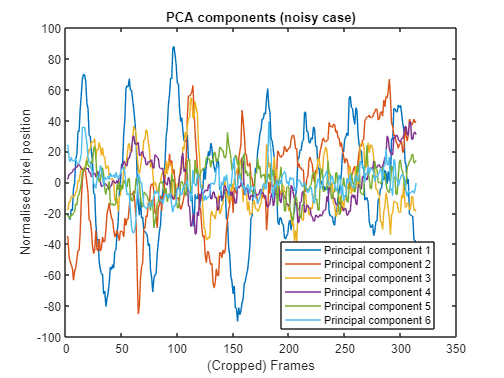

plot(Y_Noisy(1,:))
title('PCA components (noisy case)')
xlabel('(Cropped) Frames')
ylabel('Normalised pixel position')

hold on
plot(Y_Noisy(2,:))
plot(Y_Noisy(3,:))
plot(Y_Noisy(4,:))
plot(Y_Noisy(5,:))
plot(Y_Noisy(6,:))
legend('Principal component 1', ...
       'Principal component 2', ...
       'Principal component 3', ...
       'Principal component 4', ...
       'Principal component 5', ...
       'Principal component 6','Location','best')
hold off

### Plots PCA eigenvalues

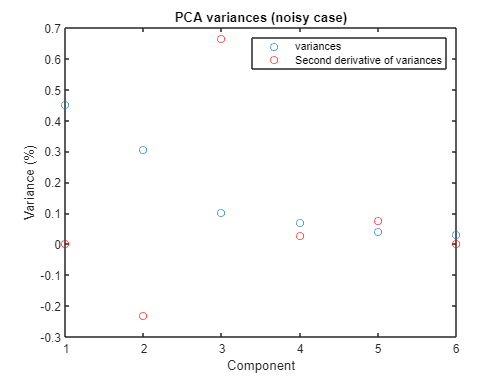

plot(lambda_Noisy/sum(lambda_Noisy), 'o')
title('PCA variances (noisy case)')
xlabel('Component')
ylabel('Variance (%)')

ddlambda_Noisy = zeros(size(lambda_Noisy));
for i = 1:length(lambda_Noisy)
    if i == 1
        ddlambda_Noisy(i) = 0;
    elseif i == length(lambda_Noisy)
        ddlambda_Noisy(i) = 0;
    else
        ddlambda_Noisy(i) = (lambda_Noisy(i+1) - 2*lambda_Noisy(i) + lambda_Noisy(i-1));
    end
end

hold on
plot(ddlambda_Noisy/sum(abs(ddlambda_Noisy)), 'ro')
legend('variances','Second derivative of variances')
hold off

## Analysis

### Gets fast fourier transforms of largest principal components 

%%% Modified from fft documentation

Fs_Noisy = 1;            % Sampling frequency                    
T_Noisy = 1/Fs_Noisy;             % Sampling period       
L_Noisy = sz_Noisy;             % Length of signal
t_Noisy = (0:L_Noisy-1)*T_Noisy;        % Time vector

f_1 = fft(Y_Noisy(1,:))

f_1 = 	1.0e+03 *

   0.0000 + 0.0000i   0.8207 + 0.6581i  -1.4086 + 1.0532i   2.3035 + 0.6033i  -0.6704 - 1.1528i   1.4032 + 1.3532i   0.6075 - 1.1405i   1.1902 - 0.9457i  -6.6430 - 1.4946i  -1.4402 + 0.3721i  -0.4061 + 0.2853i  -0.3590 - 0.2331i  -0.3201 + 0.4976i  -0.4265 + 0.0745i  -0.5212 - 0.3290i  -0.2940 + 0.1406i   0.1581 + 0.2132i   0.4897 + 0.1109i   0.2650 - 0.6295i   0.1247 + 0.0180i   0.1534 + 0.1247i   0.1324 + 0.1501i   0.2142 + 0.3373i   0.1214 - 0.2119i   0.0597 - 0.0707i  -0.3347 + 0.0898i   0.1259 - 0.0507i   0.0895 - 0.3566i  -0.1059 - 0.0267i  -0.0315 + 0.1085i   0.0655 - 0.1586i   0.1133 + 0.0564i   0.0788 + 0.0707i  -0.1065 - 0.0692i  -0.0973 + 0.0402i   0.0899 + 0.0752i  -0.1491 - 0.0431i  -0.0368 + 0.1064i   0.0641 - 0.0243i  -0.0678 + 0.1137i   0.0345 - 0.1359i   0.1179 - 0.0998i   0.1596 - 0.1057i  -0.0175 - 0.1617i   0.0863 - 0.1678i  -0.1288 + 0.1658i   0.1475 - 0.0635i   0.2018 - 0.0718i  -0.0688 + 0.1254i  -0.0051 - 0.1523i


f_2 = fft(Y_Noisy(2,:))

f_2 = 	1.0e+03 *

  -0.0000 + 0.0000i   0.5083 + 3.8693i  -0.7797 + 2.0647i   0.8629 + 2.1515i  -0.3110 - 0.3176i  -1.6381 + 1.5317i   0.7888 + 0.2574i  -1.5395 - 0.6355i   1.5819 + 0.4474i  -0.7335 + 0.0824i  -0.7410 + 1.0456i   0.2372 + 0.6662i  -0.1063 - 0.0268i  -0.2849 + 1.0063i   0.4281 + 0.6919i  -0.5704 + 0.9099i   0.2784 + 1.4215i   0.9010 + 0.2975i  -0.1643 - 0.3853i  -0.4514 + 0.4835i   0.4783 + 0.2626i  -0.0213 + 0.2387i   0.4470 - 0.0771i   0.1120 - 0.1644i  -0.1729 + 0.0576i   0.0738 + 0.2650i   0.3250 - 0.0003i  -0.1589 + 0.0916i  -0.0814 - 0.0993i  -0.3723 + 0.1030i  -0.1844 + 0.3591i  -0.2003 + 0.3041i   0.1627 + 0.0279i  -0.1076 - 0.0747i   0.0648 + 0.2247i  -0.2344 + 0.0379i   0.2190 + 0.2552i   0.0829 + 0.0883i  -0.0437 - 0.0566i  -0.1417 + 0.1226i   0.0347 + 0.2725i   0.0880 + 0.2314i   0.0525 - 0.1418i  -0.0008 + 0.0616i  -0.1613 + 0.0955i  -0.0361 + 0.0723i   0.0680 + 0.1697i  -0.1624 - 0.1435i   0.0053 - 0.0317i   0.0227 + 0.1022i


### Plot absolute values of the FFT

#### PC1

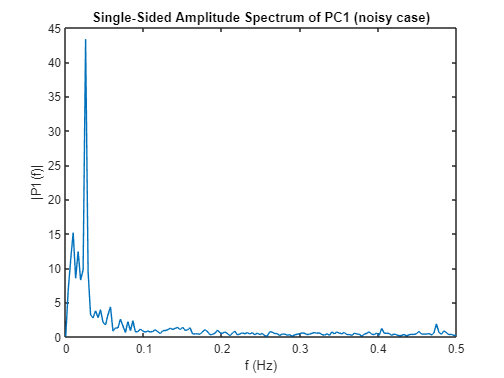

%%% Modified from fft documentation

P2_1_Noisy = abs(f_1/L_Noisy);
P1_1_Noisy = P2_1_Noisy(1:L_Noisy/2+1);
P1_1_Noisy(2:end-1) = 2*P1_1_Noisy(2:end-1);

f1_Noisy = Fs_Noisy*(0:(L_Noisy/2))/L_Noisy;
plot(f1_Noisy,P1_1_Noisy) 
title('Single-Sided Amplitude Spectrum of PC1 (noisy case)')
xlabel('f (Hz)')
ylabel('|P1(f)|')


P1_1_max_Noisy = max(P1_1_Noisy)

P1_1_max_Noisy = 43.3696

f1_max_Noisy = f1_Noisy(P1_1_Noisy == P1_1_max_Noisy)

f1_max_Noisy = 0.0255

#### PC2

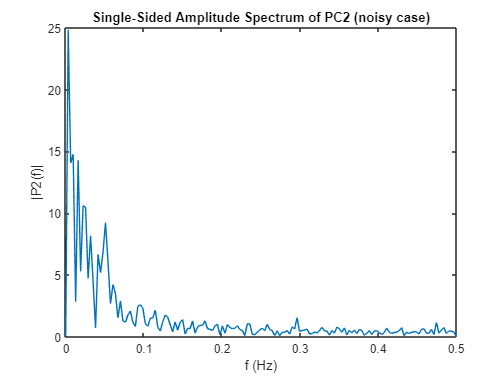

%%% Modified from fft documentation

P2_2_Noisy = abs(f_2/L_Noisy);
P1_2_Noisy = P2_2_Noisy(1:L_Noisy/2+1);
P1_2_Noisy(2:end-1) = 2*P1_2_Noisy(2:end-1);

f2_Noisy = Fs_Noisy*(0:(L_Noisy/2))/L_Noisy;
plot(f2_Noisy,P1_2_Noisy) 
title('Single-Sided Amplitude Spectrum of PC2 (noisy case)')
xlabel('f (Hz)')
ylabel('|P2(f)|')


P1_2_max = max(P1_2_Noisy)

P1_2_max = 24.8572

f2_max = f2_Noisy(P1_2_Noisy == P1_2_max)

f2_max = 0.0032

### Use least square fitting to estimate sine waves for PCs (assuming simple harmonic motion)

#### PC1

%%% Minimise LSE: sum( abs( f(x_k)-y_k )^2 )
%%% Function: f(x) = A*sin(omega_n*x + phi)
x_Noisy = 1:sz_Noisy;
LSE_sin_1_Noisy = @(n) sum( abs( n(1)*sin(n(2)*x_Noisy + n(3))-Y_Noisy(1,:) ).^2 );
n0_1_Noisy = [P1_1_max_Noisy, f1_max_Noisy*2*pi, 0*(pi/180)];
coef_1_Noisy = fminsearch(LSE_sin_1_Noisy,n0_1_Noisy)

coef_1_Noisy =    45.7330    0.1569   -1.0655


Error_1_Noisy = LSE_sin_1_Noisy(coef_1_Noisy)

Error_1_Noisy = 1.3587e+05

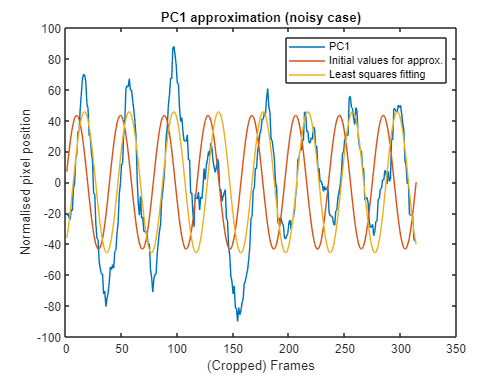


y_1_Noisy = coef_1_Noisy(1)*sin(coef_1_Noisy(2)*x_Noisy + coef_1_Noisy(3));
y0_1_Noisy = n0_1_Noisy(1)*sin(n0_1_Noisy(2)*x_Noisy + n0_1_Noisy(3));

plot(Y_Noisy(1,:))
title('PC1 approximation (noisy case)')
xlabel('(Cropped) Frames')
ylabel('Normalised pixel position')
hold on
plot(y0_1_Noisy)
plot(y_1_Noisy)
legend('PC1','Initial values for approx.', 'Least squares fitting')
hold off

#### PC2

LSE_sin_2_Noisy = @(n) sum( abs( n(1)*sin(n(2)*x_Noisy + n(3))-Y_Noisy(2,:) ).^2 );
n0_2_Noisy = [P1_2_max, f2_max*2*pi, 90*(pi/180)];
coef_2_Noisy = fminsearch(LSE_sin_2_Noisy,n0_2_Noisy)

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 148561.296618 



coef_2_Noisy =   277.2141    0.0009    6.1401


Error_2_Noisy = LSE_sin_2_Noisy(coef_2_Noisy)

Error_2_Noisy = 1.4856e+05

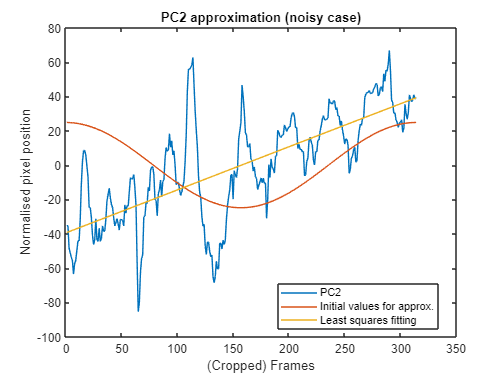


y_2_Noisy = coef_2_Noisy(1)*sin(coef_2_Noisy(2)*x_Noisy + coef_2_Noisy(3));
y0_2_Noisy = n0_2_Noisy(1)*sin(n0_2_Noisy(2)*x_Noisy + n0_2_Noisy(3));

plot(Y_Noisy(2,:))
title('PC2 approximation (noisy case)')
xlabel('(Cropped) Frames')
ylabel('Normalised pixel position')
hold on
plot(y0_2_Noisy)
plot(y_2_Noisy)
legend('PC2','Initial values for approx.', 'Least squares fitting','Location','best')
hold off

## Various functions are here:

### Imports data

function camData = importCamData(Dataset,Camera)

Data_path =join( ['C:' ...
    '\Users' ...
    '\dakin' ...
    '\Oscillating-Mass-and-Dimensionality-Reduction' ... 
    '\Project_Datasets' ...
    '\',Dataset, ... 
    '\',Camera] ); % Change to location of files

camData = load( Data_path );

end



### Shows cropped and uncropped video frame

%%% Shows cropped and uncropped video frame
function [im_1,im_2] = showFrames(frameNum,vidFrame,width,height)

normFrame = vidFrame(:,:,:,frameNum);
im_1 = image(normFrame);

croppedFrame = vidFrame(height,width,:,frameNum);
im_2 = image(croppedFrame);

end



### Finds pixel that corresponds to cap

%%% Finds the pixels that correspond to the cap
function cap_Pixels = getCapPixels(croppedFrame1,croppedFrame,x,y,d)

if nargin == 4
    d = 10;
elseif nargin == 2
    x = 82;
    y = 198;
end


r = croppedFrame1(end-y,x,1);
g = croppedFrame1(end-y,x,2);
b = croppedFrame1(end-y,x,3);


cap_Pixels = ((croppedFrame(:,:,1) >= r - d) & (croppedFrame(:,:,1) <= r + d)) ...
            &((croppedFrame(:,:,2) >= g - d) & (croppedFrame(:,:,2) <= g + d)) ...
            &((croppedFrame(:,:,3) >= b - d) & (croppedFrame(:,:,3) <= b + d));
end



### Finds the pixels that correspond to the cap using brightness

%%% Finds the pixels that correspond to the cap
function cap_Pixels = getCapPixelsBright(croppedFrame,d)

if nargin == 1
    d = 10;
end

br = max( rgb2gray(croppedFrame) );

cap_Pixels = ((croppedFrame(:,:,1) >= br - d) & (croppedFrame(:,:,1) <= br + d)) ...
            &((croppedFrame(:,:,2) >= br - d) & (croppedFrame(:,:,2) <= br + d)) ...
            &((croppedFrame(:,:,3) >= br - d) & (croppedFrame(:,:,3) <= br + d));
end

### Finds the bounds for the cap pixels

%%% Finds the bounds for the cap pixels
function [top,bottom,left,right] = Boundaries(cap_Pixels)

top = 0;
bottom = 0;
left = 0;
right = 0;

sz_row = size(cap_Pixels,1);
for i = 1:sz_row
    findOne = size(find(cap_Pixels(i,:)));
    if findOne(2) ~= 0
        top = sz_row - i;
        break;
    end
end

for i = 1:sz_row
    findOne = size(find(cap_Pixels(end-i,:)));
    if findOne(2) ~= 0
        bottom = i;
        break;
    end
end

sz_col = size(cap_Pixels,2);
for i = 1:sz_col
    findOne = size(find(cap_Pixels(:,i)));
    if findOne(1) ~= 0
        left = i;
        break;
    end
end

for i = 1:sz_col
    findOne = size(find(cap_Pixels(:,end-i)));
    if findOne(1) ~= 0
        right = sz_col - i;
        break;
    end
end

end



### Finds centre from bounds

%%% Finds centre from bounds
function [x,y] = centre(top,bottom,left,right)

y = mean([top,bottom]);
x = mean([left,right]);

end



### Finds centre from averaging the number of pixels

%%% Finds centre from averaging the number of pixels
function [x,y] = centre_avg(cap_Pixels)
[sz_row,sz_col] = size(cap_Pixels);

x = 0;
x_num = 0;
for i = 1:sz_col
    x = x + sum(cap_Pixels(:,i))*i ;
    x_num = x_num + sum(cap_Pixels(:,i)) ;
end
x = x/x_num;

y = 0;
y_num = 0;
for i = 1:sz_row
    y = y + sum(cap_Pixels(i,:))*i ;
    y_num = y_num + sum(cap_Pixels(i,:)) ;
end
y = sz_row - y/y_num;

end



### Gets X and Y data from camera data

%%% Gets X and Y data from camera data
function [X,Y] = getXY(camData,width,height,x,y,d)

if nargin == 5
    d = 10;
elseif nargin == 3
    x = 82;
    y = 198;
elseif nargin == 1
    width = 250:450;
    height = 200:425;
end

numFrames = size(camData(1,1,1,:),4);
croppedFrame1 = camData(height,width,:,1);

X = zeros(1,numFrames);
Y = zeros(1,numFrames);

for i = 1:numFrames
    croppedFrame = camData(height,width,:,i);
    cap_Pixels = getCapPixels(croppedFrame1,croppedFrame,x,y,d);
    
    
    [x_avg,y_avg] = centre_avg(cap_Pixels);
    X(i) = x_avg;
    Y(i) = y_avg;
end

end



### Gets X and Y data from camera data using brightness

%%% Gets X and Y data from camera data
function [X,Y] = getXYBright(camData,width,height,d)

if nargin == 3
    d = 10;
elseif nargin == 1
    width = 250:450;
    height = 200:425;
end

numFrames = size(camData(1,1,1,:),4);

X = zeros(1,numFrames);
Y = zeros(1,numFrames);

for i = 1:numFrames
    croppedFrame = camData(height,width,:,i);
    cap_Pixels = getCapPixelsBright(croppedFrame,d);
    
    [x_avg,y_avg] = centre_avg(cap_Pixels);
    X(i) = x_avg;
    Y(i) = y_avg;
end

end



### Plots X and Y on the same graph

%%% Plots X and Y on the same graph
function plotXY(X,Y,d,Dataset)

plot(X)
if nargin == 4
    title_text = join(['Plots for ',inputname(1), ...
        ' and ',inputname(2), ...
        ' (data = ',Dataset,', d = ',num2str(d),')']);
else
    title_text = join(['Plots for ',inputname(1), ...
        ' and ',inputname(2), ...
        ' (d = ',num2str(d),')']);
end
title(title_text)
xlabel('Frame')
ylabel('Pixel position (from bottom left)')
hold on
plot(Y)
legend('X','Y')
hold off

end

